# **Projet DMLV : A new approach to model regime switching**

clc ; clear ; clear all;

## Première partie - Application sur données Hamilton

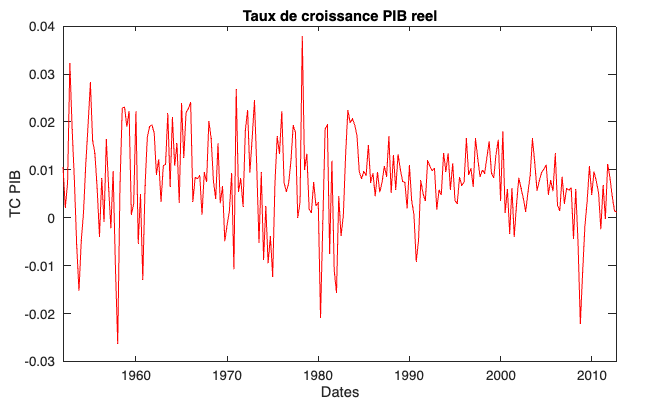

% Importation des données
data_gdp = readtable("Data/GDP US.xlsx", "Sheet","Quarterly");
dates = data_gdp.observation_date;
gdp = data_gdp.GDPC1;

% Passage au log et taux de croissance
log_gdp = log(gdp);
growth_gdp = diff(log_gdp, 1);
dates_growth_gdp = dates(2:length(dates));

% Conserve les mêmes périodes que dans l'étude : 1952:Q1 - 2012:Q4
index_backtest = dates_growth_gdp >= '01-Jan-1952' & dates_growth_gdp <= '01-Oct-2012';
growth_gdp_hamitlon = growth_gdp(index_backtest);

% Visualisation graphique
f0 = figure("Units","normalized","Position",[0 0 1 1]);
t = tiledlayout(1,1,'TileSpacing','compact','Padding','compact');
nexttile();
plot(dates_growth_gdp(index_backtest), growth_gdp_hamitlon, 'r');title("Taux de croissance PIB reel");
xlabel("Dates");ylabel("TC PIB");

## Deuxième partie - Simulations